clc
clear
close all

## parameters

% load ss
load('Assignment_Data_SC42145.mat');

% operational parameters
P_rated = 1.8E6; % W
T_rated = 1E4; % Nm
W_rated = 180; % rad/s
V_lin = 16; % m/s


open loop analysis

SISO_ss = FWT(1,1); % Beta to Omega
set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
figsize = [0,0,6,2/3 *6]

figsize =      0     0     6     4


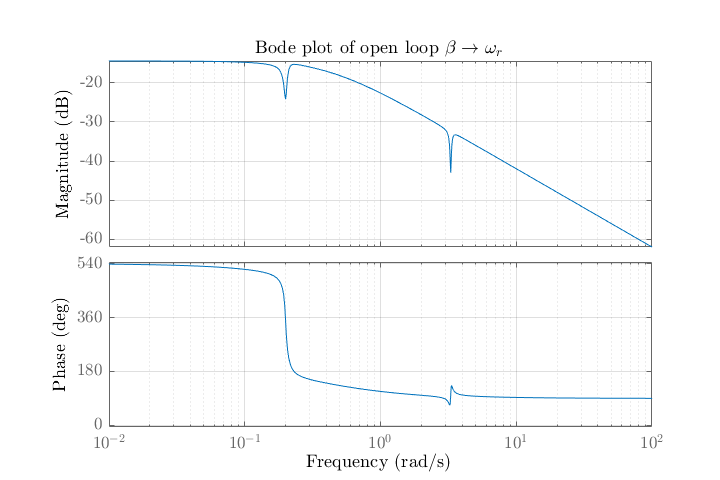


figure('units','inch','position',figsize);
bode(tf(FWT(1,1)))
grid on
xlabel('Frequency','interpreter', 'latex')
ylabel('Phase','interpreter', 'latex')
title('Bode plot of open loop $\beta \to \omega_r$','interpreter', 'latex')
hs = findall(gcf, 'type', 'axes');
ha = get(hs(3), 'title');
ha.String = ''; % remove the subtitle "From: u1 To: y1"
saveas(gcf, 'Figures/ch1_siso_openloop.eps',  'epsc')

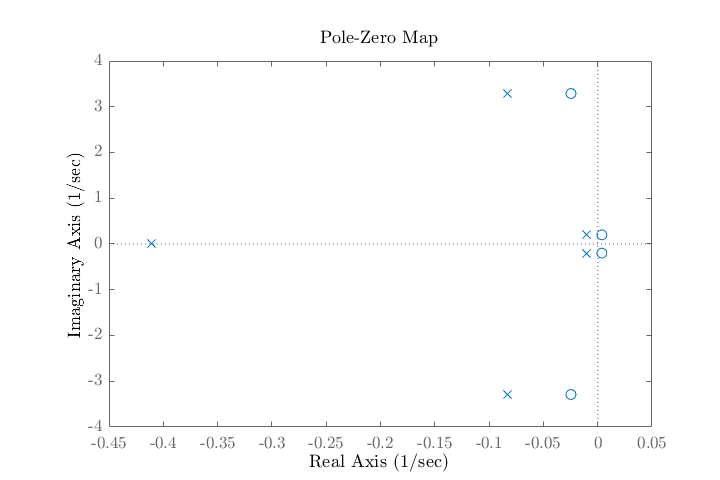



f = figure('units','inch','position',figsize);
h  =pzplot(SISO_ss);
h.AxesGrid.YUnits = '1/sec'; 
h.AxesGrid.XUnits = '1/sec'; 
xlabel('Real Axis', 'interpreter', 'latex')
ylabel('Imaginary Axis','interpreter', 'latex') % Really no need for this line
title('Pole-Zero Map','interpreter', 'latex')
saveas(gcf, 'Figures/ch1_siso_pzmap.eps',  'epsc')

## SISO controller


figure(1);
subplot(1,2,1); margin(SISO_ss)
[gain_margin,phase_margin,w_crossover_g,w_crossover_p] = margin(SISO_ss)

subplot(1,2,2); pzmap(SISO_ss);

poles = pole(SISO_ss)
zeros_ = zero(SISO_ss)

tf(SISO_ss)

SISO_ss


t = linspace(0,200,1000);
input= ones(1, length(t)); %reference

om_filter = 0.1;
low_pass_filter = tf([1],[1/om_filter, 1]); %first order low pass
%low_pass_filter = tf([1],[1]); %first order low pass

figure()
margin(low_pass_filter)
title('Low pass filter')
grid on

controller = pid(-0.1, -0.13 ,-0.2);  
%all negative as the rotational speed is negatively correlated with the
%rotational speed around the linearization point

lead_lag = tf([1e20 1], [1e10 1]);
lead_lag = tf([1], [1]);

% figure()
% margin(lead_lag)
% title('Lead lag')
% grid on

controller = lead_lag*controller;


closed_loop = inv(1+SISO_ss*controller*low_pass_filter)*SISO_ss*controller*low_pass_filter; %feedback

open_loop = SISO_ss*controller*low_pass_filter;

closed_loop = feedback(open_loop, 1);

bodeplot(closed_loop)

sensitivity = 1/(1+controller*SISO_ss);

[gain_margin,phase_margin,w_crossover_g,w_crossover_p] = margin(open_loop)
title('open loop')

%margin(sensitivity)
%title('sensitivity')

bandwidth_ = bandwidth(closed_loop)
%pid(-4,0,0) gives about 0.1 Hz bandwidth --> good

grid on
%title("Closed loop")

figure()
lsim(closed_loop, input, t)
info = stepinfo(closed_loop)


G = FWT;
controller = [pid(-0., -0.265 ,-0.0), 0,0; 0,0,0];
closed_loop = feedback(G, -controller');

disturbance_v = zeros(size(t));
t_half = length(t)/4;
disturbance_v(t_half:end) = 1
input = [zeros(size(t));zeros(size(t));disturbance_v];
lsim(closed_loop, input, t)

